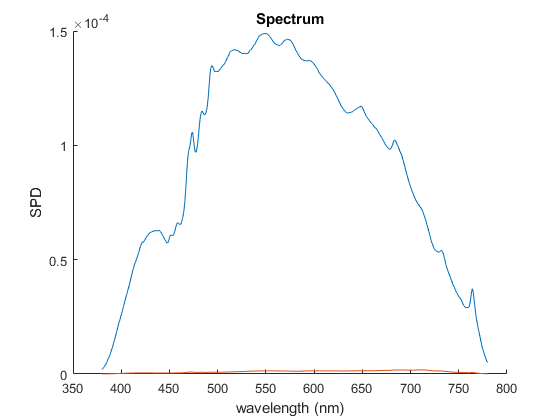

load('ss.mat')

clf
hold on
sall.plot
s0.plot



tall = sall.amplitude;
t0 = s0.amplitude;



offset = 0.4

offset = 0.4000

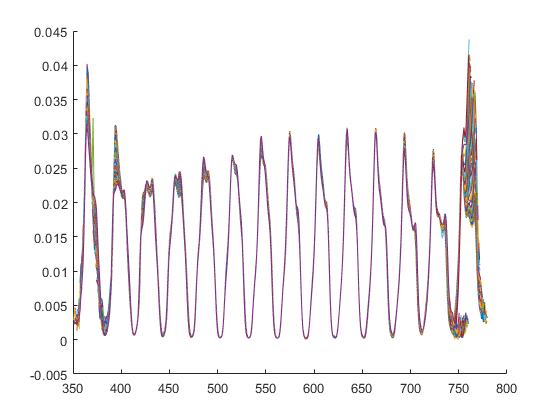

clf
hold on
%for i = 1:74
for i = 1:1:74
    %ss{i}.plot
    t = ss{i}.amplitude - t0;
    tran = t ./ tall;
    plot([380:780]-i*offset,tran)
end

load('col_wl_400_750.mat','col_wl')

vall = 1:1024;
ol.setColumn1024(vall)
meaall = cs.measure;

v0 = zeros(1,1024);
ol.setColumn1024(v0)
mea0 = cs.measure;

load("transparent.mat")
tref = meaall.amplitude - mea0.amplitude;

load('col_wl_400_750.mat','col_wl')

trans_all = {};
for i = 1:length(col_wl)
    col = col_wl(i,1)
    vec = LightSim.multiple_peaks(col);
    ol.setColumn1024(vec)
    mea = cs.measure;
    tmea = mea.amplitude - mea0.amplitude;
    trans = tmea ./ tref;
    trans_all{i} = trans;
end

col = 72

col = 98

col = 126

col = 152

col = 179

col = 202

col = 226

col = 248

col = 277

col = 301

col = 327

col = 355

col = 380

col = 405

col = 429

col = 454

col = 481

col = 505

col = 530

col = 556

col = 583

col = 608

col = 633

col = 658

col = 682

col = 708

col = 734

col = 757

col = 782

col = 810

col = 834

col = 860

col = 884

col = 908

col = 933

col = 956

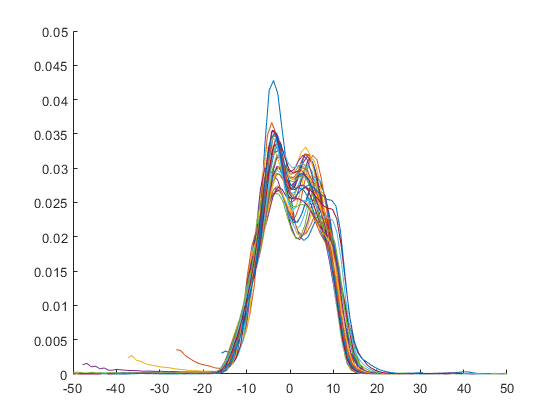

clf
hold on
for i = 1:length(col_wl)
    col = col_wl(i,1);
    plot([380:780]-col*0.4-367,trans_all{i})
end
axis([-50 50 0 0.05])

clf
hold on
i = 1;
col = col_wl(i,1)

col = 72

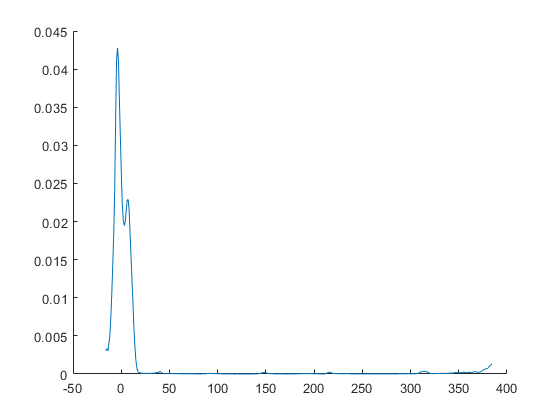

plot([380:780]-col*0.4-367,trans_all{i})

%axis([-50 50 0 0.05])

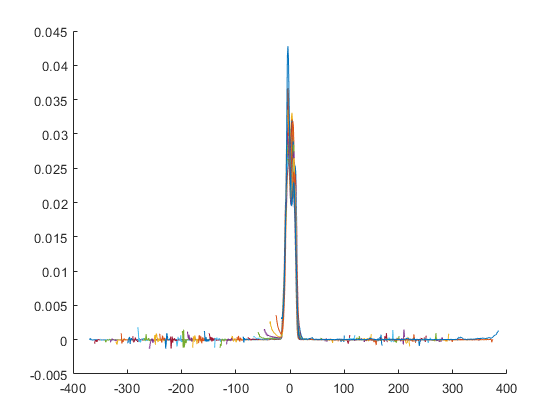

clf
hold on
for i = 1:length(col_wl)
    col = col_wl(i,1);
    [X Y] = meshgrid([380:780]-col*0.4-367,i);
    plot3(X,Y,trans_all{i})
end
view([0 0])

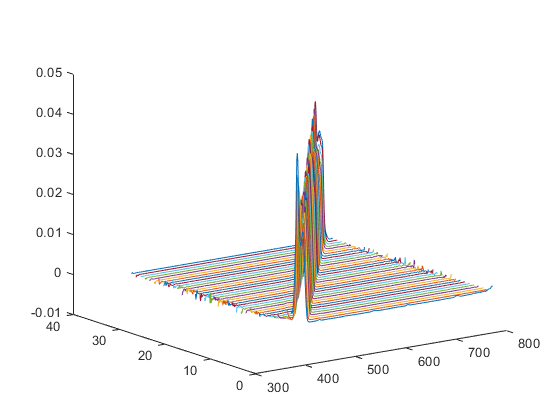

clf
hold on
for i = 1:length(col_wl)
    [X Y] = meshgrid(380:780,i);
    plot3(X,Y,trans_all{i})
end
view([-36 17])